# Post Calculations of Ising

## Constants

T_crit_theo=2/log(1+sqrt(2))

T_crit_theo = 2.2692

## Import data to multidim array

[N_vals512,T_vals512,data512] = importMultiParallel('IsingResultsWolff512_corr1.tsv');

numOfTemps =     16


numOfIterations =       100000


importSize =      3199999           7


Unable to perform assignment because the size of the left side is 16-by-1 and the size of the right side is 1-by-0.

Error in importMultiParallel (line 15)
   T_vals(:,i)= unique(import(import==N_vals(i),2))';

%remove N=256
%data(end,:,:,:)=[];
%N_vals(end)=[];
%T_vals(:,end)=[];

% save to hdf5
h5create('wolffUntil256.h5','/ising',size(data),'Datatype','double','ChunkSize',size(data),'Deflate',9)
h5write('wolffUntil256.h5', '/ising', data)

## Reweight magnetization

for i=2.2727:0.001:2.35484
    for j=4:4
        [N_vals,T_vals,data] = addReweightToData(N_vals,T_vals,data,i,j);
    end
end

%clean outliners
T_vals([40,42],:)=[];
data(:,[40,42],:,:)=[];

% sort new temps again ascending
sampleIndex=0
[T_vals(:,sampleNindex),I]=sort(T_vals(:,sampleNindex));
data(sampleNindex,:,:,:)=data(sampleNindex,I,:,:);

## Reduce data to mean and std

[O_mean,O_std,O_var,O_var_err,O_weight,O_corrLength] = ReduceObservableMulti(data);

## Plot energy

figure('Position',[10 10 1200 900])
clf
subplot(2,2,1)
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1), ...
    %    reshape(O_std(i,:,1,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("normalized energy E")
legend("Location","best")
title("energy E")
%saveas(gcf,'./plots/measuredAndRewEnergy.png');

## Plot magnetization

subplot(2,2,2)
for i=1:size(data,1)
    %errorbar(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1), ...
    %    reshape(O_std(i,:,2,:),[],1),'DisplayName',"N="+N_vals(i))
    plot(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("absolute magnetization M")
legend("Location","best")
title("magnetization M")
%saveas(gcf,'./plots/measuredAndRewMagnet.png');

## heat capacity

heatCap=reshape(O_var(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;
heatCap_err=reshape(O_var_err(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;

subplot(2,2,3)
for i=1:size(data,1)
    if i==4
        plot(T_vals(1:end-80,i),heatCap(1:end-80,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    else
        plot(T_vals(:,i),heatCap(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    end

    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")
title("heat capacity C")

## susceptibility

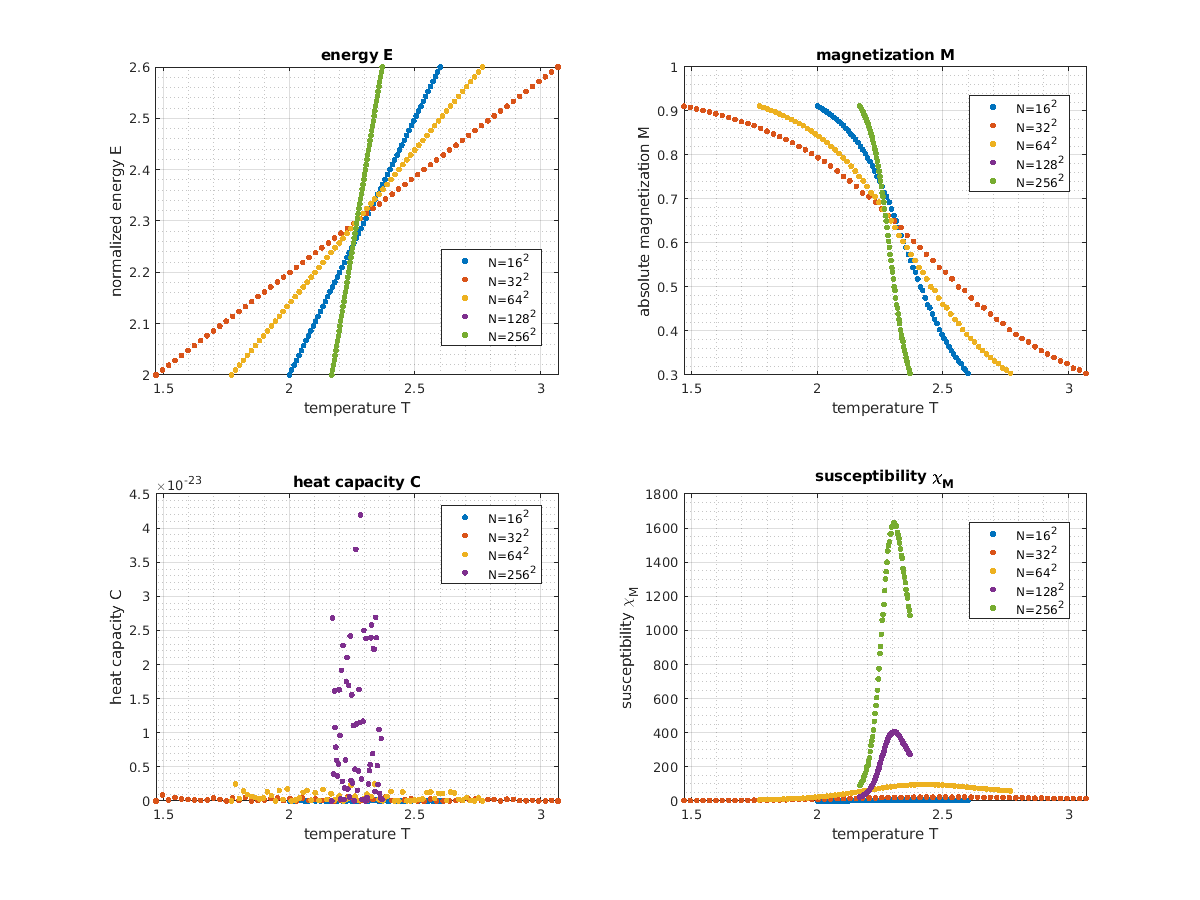

suscept=reshape(O_var(:,:,2),length(N_vals),[])'./T_vals.*N_vals.^2;
suscept_err=reshape(O_var_err(:,:,2),length(N_vals),[])'./T_vals.*N_vals.^2;

subplot(2,2,4)
for i=1:size(data,1)
    plot(T_vals(:,i),suscept(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10)
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("susceptibility \chi_M")
legend("Location","best")
title("susceptibility \chi_M")
saveas(gcf,'./plots/measuredAndRewObservables.png');

## Fit magnetization

figure('Position', [10 10 1200 900])
clf
for i=1:size(data,1)
    [t_cleaned,y_cleaned]=prepareCurveData(T_vals(:,i), reshape(O_mean(i,:,2,:),[],1).*N_vals(i).^2);
    %if(i==1)
    %    [t_cleaned,y_cleaned]=prepareCurveData(T_vals(1:32,i), reshape(O_mean(i,1:32,2,:),[],1).*N_vals(i).^2);
    %end
    x=t_cleaned;%[2:0.01:3 ]';
    [t_cleaned,ia]=unique(t_cleaned);
    y=y_cleaned;% interp1(t_cleaned,y_cleaned(ia),x,"linear");

    ft = fittype( 'a*abs(T-Tc)^beta+1', 'independent', 'T', 'dependent', 'y' );
    excludedPoints = y < N_vals(i).^2 /2;
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [2 -Inf -Inf];
    opts.StartPoint = [3 N_vals(i).^2 0.8];
    opts.Upper = [5 Inf 1];
    opts.Exclude = excludedPoints;
    [fitM_exponent, gof_M_exponent] = fit( x, y, ft, opts )


    T_c_N(i)=fitM_exponent.Tc;
    beta_N(i)=fitM_exponent.beta;

    subplot(2,3,i)
    p=plot( fitM_exponent, x,y,excludedPoints);
    p(1).MarkerSize=10;
    grid on
    box on
    xlabel("temperature T")
    ylabel("magnetization M")
    title("magnetization N="+N_vals(i)+"^2, T_c="+fitM_exponent.Tc)
    legend("Location","best")
end

fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.462  (2.448, 2.476)
       a =       299.7  (294.4, 305)
       beta =      0.3038  (0.2781, 0.3295)

gof_M_exponent = struct with fields:
           sse: 263.9826
       rsquare: 0.9941
           dfe: 41
    adjrsquare: 0.9939
          rmse: 2.5374


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.702  (2.664, 2.74)
       a =       892.7  (882.5, 902.8)
       beta =      0.3029  (0.2773, 0.3285)

gof_M_exponent = struct with fields:
           sse: 4.2187e+03
       rsquare: 0.9941
           dfe: 41
    adjrsquare: 0.9939
          rmse: 10.1437


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =        2.54  (2.516, 2.563)
       a =        4120  (4088, 4151)
       beta =      0.3026  (0.277, 0.3283)

gof_M_exponent = struct with fields:
           sse: 6.7479e+04
       rsquare: 0.9941
           dfe: 41
    adjrsquare: 0.9939
          rmse: 40.5689


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.323  (2.319, 2.328)
       a =   2.682e+04  (2.562e+04, 2.803e+04)
       beta =      0.3026  (0.277, 0.3282)

gof_M_exponent = struct with fields:
           sse: 1.0796e+06
       rsquare: 0.9941
           dfe: 41
    adjrsquare: 0.9939
          rmse: 162.2693


fitM_exponent =      General model:
     fitM_exponent(T) = a*abs(T-Tc)^beta+1
     Coefficients (with 95% confidence bounds):
       Tc =       2.323  (2.319, 2.328)
       a =   1.073e+05  (1.025e+05, 1.121e+05)
       beta =      0.3026  (0.277, 0.3282)

gof_M_exponent = struct with fields:
           sse: 1.7273e+07
       rsquare: 0.9941
           dfe: 41
    adjrsquare: 0.9939
          rmse: 649.0712


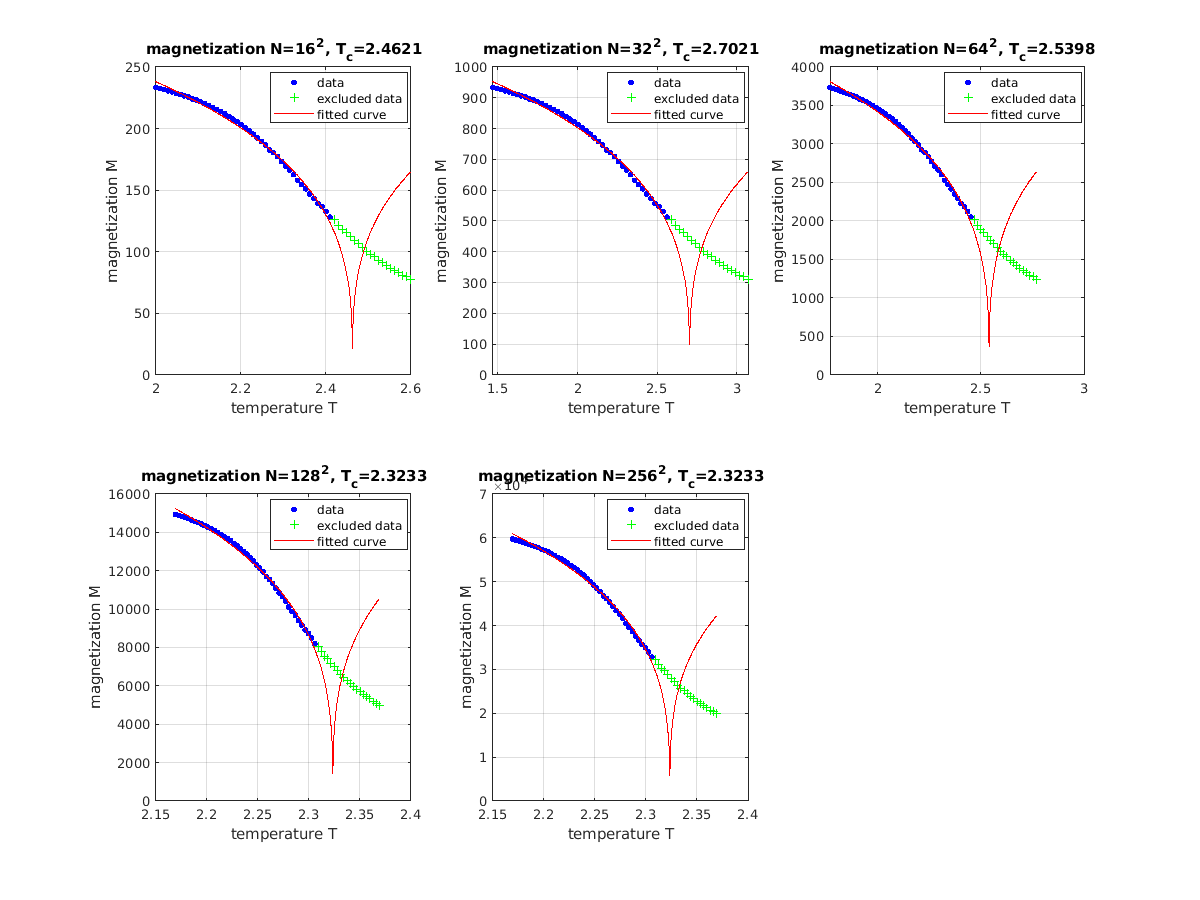

saveas(gcf,'./plots/measuredAndRewMagnet_fit.png');

# Fit critical exponents

figure('Position', [10 10 1200 900])
clf
subplot(2,2,4)

## critical T for finite size systems

T_c_N

T_c_N =     2.4621    2.7021    2.5398    2.3233    2.3233


T_c_N_err=abs(T_c_N-T_crit_theo);

ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 0.4];
opts.StartPoint = [0 1];
opts.Upper = [Inf 1.2];

% Fit model to data.
[fitMagnetTcrit,~] = fit( log(N_vals.^2)',log(T_c_N_err)', ft)

fitMagnetTcrit =      Linear model Poly1:
     fitMagnetTcrit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     -0.3334  (-0.8421, 0.1754)
       p2 =      0.8483  (-3.499, 5.196)

p1=fitMagnetTcrit.p1*-1;
nu_err=round(table(diff(confint(fitMagnetTcrit))/2).Var1(1)/p1.^2,3);

plot(fitMagnetTcrit,log(N_vals.^2),log(T_c_N_err))
title("finite size scale error of T_c: \nu="+round(1/p1,3)+"+-"+nu_err)
xlabel("log Number of spins N")
ylabel("log |T_c-T_c(N)|")
grid on
%saveas(gcf,'./plots/Tcrit_err_N_nu.png')

## beta for finite size systems

subplot(2,2,2)
ft = fittype( 'poly1' );

% Fit model to data.
x=log(N_vals(1:end).^2)';
y=log(abs(beta_N(1:end)))';
[fitbeta,~] = fit( x,y, ft )

fitbeta =      Linear model Poly1:
     fitbeta(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -0.0006535  (-0.001429, 0.0001216)
       p2 =      -1.189  (-1.196, -1.182)


beta=fitbeta.p1*-1;
beta_err=round(table(diff(confint(fitbeta))/2).Var1(1),3);

plot(fitbeta,x,y)
title("finite size scale beta: \beta="+round(beta,3)+"+-"+beta_err)
xlabel("log Number of spins N")
ylabel("log \beta(N)")
grid on
%saveas(gcf,'./plots/magnet_beta.png')

## heat cap: alpha

Analyse now maxima in log-log-plot and fit a linear equation to the data

subplot(2,2,1)

ft = fittype( 'poly1' );

% Fit model to data.
x=log(N_vals.^2)';
y=log(max(heatCap,[],1))';
[fitHeatCapMax, gof_hcm] = fit( x, y, ft )

fitHeatCapMax =      Linear model Poly1:
     fitHeatCapMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9856  (0.8636, 1.107)
       p2 =      -62.46  (-63.5, -61.41)

gof_hcm = struct with fields:
           sse: 0.0846
       rsquare: 0.9955
           dfe: 3
    adjrsquare: 0.9940
          rmse: 0.1680


plot(fitHeatCapMax,x,y)

hcap_p1=round(fitHeatCapMax.p1,2);
hcap_p1_err=round(table(diff(confint(fitHeatCapMax))/2).Var1(1),2);

grid on
box on
xlabel("log Number of spins N")
ylabel("maximum heat capacity C")
title("heat capacity maxima: \alpha="+hcap_p1+"+-"+hcap_p1_err)
legend("Location","best")
%saveas(gcf,'./plots/heatCapMax_alpha.png')

## Susceptibility: gamma

Analyse now maxima in log-log-plot and fit a linear equation to the data

subplot(2,2,3)
ft = fittype( 'poly1' );

% Fit model to data.
[x,y]=prepareCurveData(log(N_vals), log(max(suscept,[],1)));
[fitSusceptMax, gof_susc] = fit( x,y, ft )

fitSusceptMax =      Linear model Poly1:
     fitSusceptMax(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.027  (1.978, 2.075)
       p2 =      -3.843  (-4.051, -3.634)

gof_susc = struct with fields:
           sse: 0.0034
       rsquare: 0.9998
           dfe: 3
    adjrsquare: 0.9998
          rmse: 0.0336


plot(fitSusceptMax,x,y)
%loglog(N_vals,max(suscept,[],1),'b.','DisplayName',"Data",'MarkerSize',10)
%hold on
%x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
%loglog(exp(x),exp(fitSusceptMax(x)),'-r','DisplayName',"Fit linear model")

Critical exponent

fitSusceptMax.p1

ans = 2.0265

suscept_p1_err=round(table(diff(confint(fitSusceptMax))/2).Var1(1),3)

suscept_p1_err = 0.0490

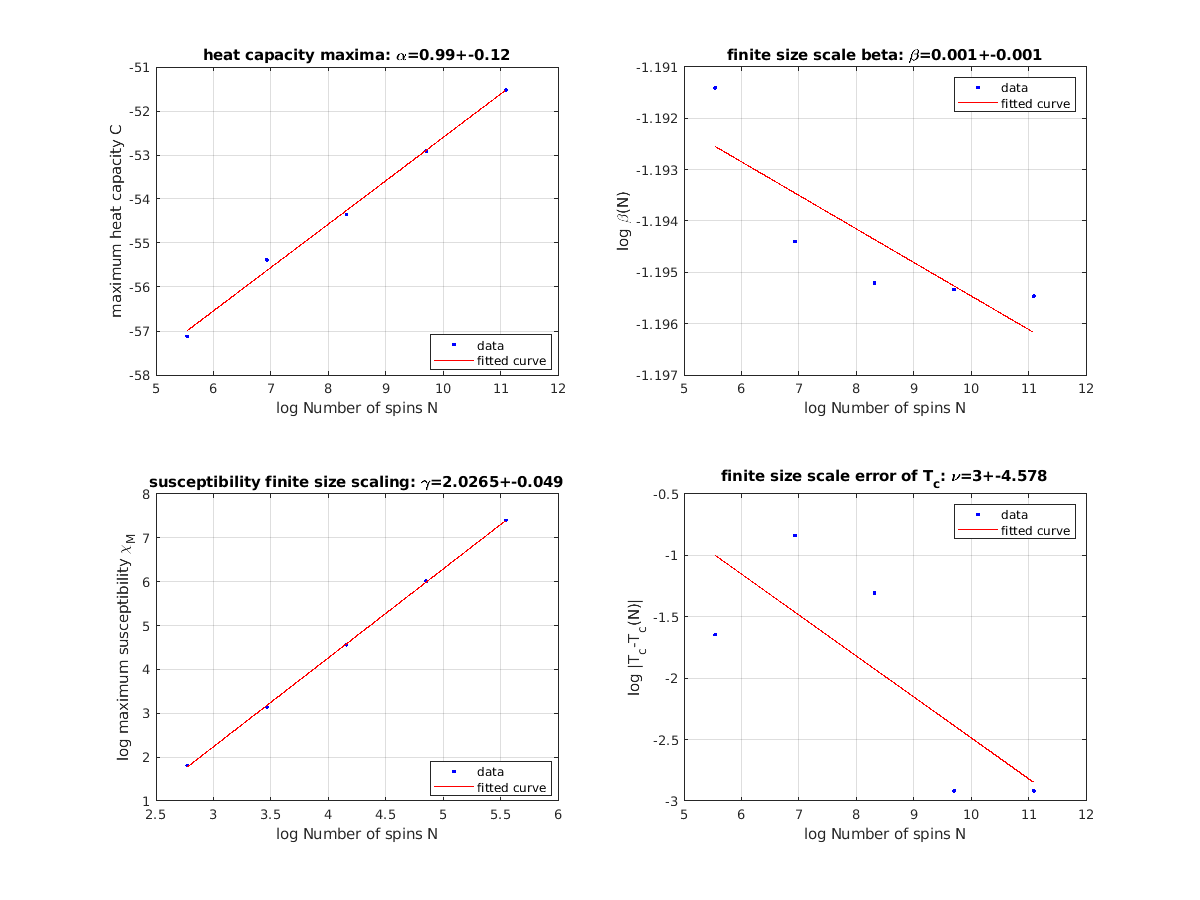


grid on
box on
xlabel("log Number of spins N")
ylabel("log maximum susceptibility \chi_M")
title("susceptibility finite size scaling: \gamma="+ (fitSusceptMax.p1)+"+-"+suscept_p1_err)
legend("Location","best")
saveas(gcf,'./plots/fitExponents.png')

fit exponent

% figure(7)
% clf
%
% ft = fittype( 'fitHeatCap(T,Tcrit,E0,-gamma)', 'independent', 'T');
% opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
% opts.Display = 'Off';
% opts.Lower = [0.001 2.2 0];
% opts.StartPoint = [0.1 2.269 0.25];
% opts.Upper = [Inf 2.3 2];
% %opts.Weights = 1./suscept_err(:,end).^2;
%
% % Fit model to data.
% [t_cleaned,y_cleaned]=prepareCurveData(T_vals(:,end), suscept(:,end));
% x=[2:0.002:3 ]';
% [t_cleaned,ia]=unique(t_cleaned);
% y=interp1(t_cleaned,y_cleaned(ia),x,"makima");
%
%
% [fitSusc_exponent, gof_susc_exponent] = fit( x,y, ft, opts )
% p=plot( fitSusc_exponent, x,y );
% p(1).MarkerSize=10;
% grid on
% box on
% %set(gca,'YScale','log')
% xlabel("temperature T")
% ylabel("susceptibility \chi")
% ylim([0,1.2*max(suscept(:,end))])
% title("susceptibility N="+N_vals(end))

exponent is:

% fitSusc_exponent.gamma
% suscept_gamma_err=table(diff(confint(fitSusc_exponent))/2).Var1(3)

# Binder Cumulants

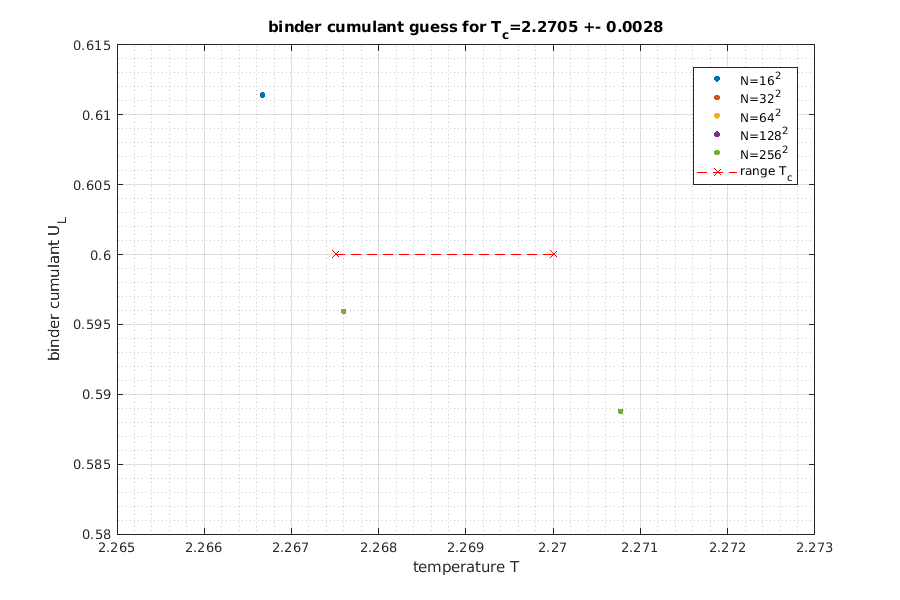

figure('Position', [10 10 900 600])
clf
U_L=(1-mean(data(:,:,2,:).^4,4)./3./mean(data(:,:,2,:).^2,4).^2)';

for i=1:size(data,1)
    plot(T_vals(:,i),U_L(:,i),'.','DisplayName',"N="+N_vals(i)+"^2",'MarkerSize',10);
    hold on
end
box on
grid on
grid minor
legend("Location","best")
title("binder cumulant guess for T_c=2.2705 +- 0.0028")
xlabel("temperature T")
ylabel("binder cumulant U_L")


xlim([2.265 2.273])
%ylim([0.534 0.666])
line([2.2675,2.27],[0.6,0.6],'Color','red','LineStyle','--','Marker','x','DisplayName','range T_c')
saveas(gcf,'./plots/binderCumulant_Tcrit.png')